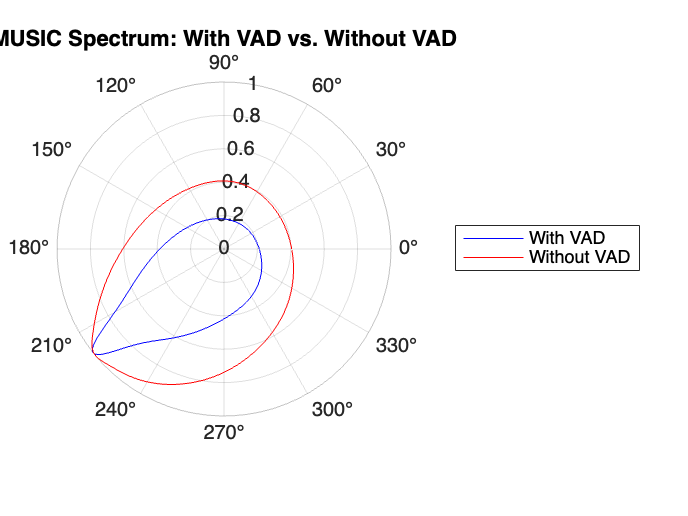

base_folder = '/Users/macos/Documents/MATLAB/Simulation_capstone/dataset/meetingroom10/speaking 45 degrees.wav';
[audio, fs] = audioread(base_folder);
assert(size(audio, 2) == 4, 'Expected 4-channel WAV file');

c = 343;              % Speed of sound (m/s)
d = 0.06;             % Distance between mics
N = 4096;             % Frame size
hop = N / 2;          % Overlap
f_low = 300;          % VAD frequency lower bound
f_high = 3400;        % Upper bound for VAD/MUSIC
vad_energy_thresh = 1e-6;
vad_zcr_thresh = 0.08;

mic_pos = [0 0; d 0; d d; 0 d];  % [x, y] for 4 mics
angles = 0:1:359;
powers_vad = zeros(size(angles));
powers_no_vad = zeros(size(angles));

num_frames = floor((size(audio, 1) - N) / hop);
for fi = 1:num_frames
    idx = (fi - 1) * hop + (1:N);
    frame = audio(idx, :) .* hann(N);

    
    x = frame(:, 1);
    energy = sum(x.^2) / N;
    zcr = sum(abs(diff(sign(x)))) / (2 * N);
    vad_pass = (energy >= vad_energy_thresh && zcr >= vad_zcr_thresh);

    
    X = fft(x .* hann(N));
    f_axis = (0:N-1) * fs / N;
    [~, peak_bin] = max(abs(X(2:N/2)));  % skip DC
    peak_freq = f_axis(peak_bin + 1);
    if peak_freq < f_low || peak_freq > f_high
        continue;
    end

    
    Xf_all = fft(frame);
    Xf_all = Xf_all(1:N/2, :);  
    Xf_all = Xf_all.';           

    R = (Xf_all * Xf_all') / (N/2);  
    % Eigendecomposition
    [Evecs, Evals] = eig(R);
    [~, idx_sort] = sort(diag(Evals), 'descend');
    Evecs = Evecs(:, idx_sort);
    En = Evecs(:, 2:end);  


    for ai = 1:length(angles)
        theta = deg2rad(angles(ai));
        direction = [cos(theta), sin(theta)];
        delays = mic_pos * direction' / c;
        steering = exp(-1j * 2 * pi * peak_freq * delays);
        P = 1 / abs(steering' * (En * En') * steering);
        
        
        if vad_pass
            powers_vad(ai) = powers_vad(ai) + real(P);
        end
        powers_no_vad(ai) = powers_no_vad(ai) + real(P);
    end
end


powers_vad = powers_vad / max(powers_vad);
powers_no_vad = powers_no_vad / max(powers_no_vad);

figure;
polarplot(deg2rad(angles), powers_vad, 'b');
hold on;
polarplot(deg2rad(angles), powers_no_vad, 'r');
legend('With VAD', 'Without VAD');
title('MUSIC Spectrum: With VAD vs. Without VAD');


corrected_angles = mod(angles + 180, 360);
[max_val_vad, max_idx_vad] = max(powers_vad);
[max_val_no_vad, max_idx_no_vad] = max(powers_no_vad);
fprintf('DoA with MUSIC (With VAD): %.1f degrees (value = %.2f)\n', corrected_angles(max_idx_vad), max_val_vad);

DoA with MUSIC (With VAD): 38.0 degrees (value = 1.00)


fprintf('DoA with MUSIC (Without VAD): %.1f degrees (value = %.2f)\n', corrected_angles(max_idx_no_vad), max_val_no_vad);

DoA with MUSIC (Without VAD): 40.0 degrees (value = 1.00)


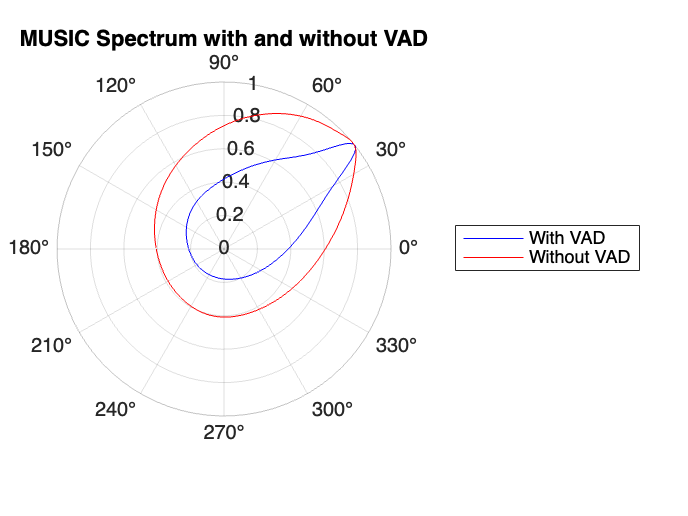


figure;
polarplot(deg2rad(corrected_angles), powers_vad, 'b');
hold on;
polarplot(deg2rad(corrected_angles), powers_no_vad, 'r');
legend('With VAD', 'Without VAD');
title('MUSIC Spectrum with and without VAD');